# Calculation of Pareto Frontier for Simulated Model Parameters

The Pareto Frontier is the set of all points that strictly dominate the other points.  In order to get an idea of what it looks like, you need to know what objectives you are assessing.  Choose

(i) increase optical cluster growth rate

(ii) increase optical / contact cluster growth rate

(iii) decrease dimension of region II-B

Let us start by visualizing the Pareto Frontier.  That means for all model parameters, gather up and plot the values of the three objectives in a 3D scatterplot.

## Read in Data

%load rate of growth of size of optical and contact clusters
saveloc = '/home/rachael/coarsegraining/Data/patchy/';
load([saveloc 'tcharsss.mat']);
grateO = mean(tcharOsss,2);
grateC = mean(tcharCsss,2);
sgrateO = std(tcharOsss,0,2)/sqrt(5);
sgrateC = std(tcharCsss,0,2)/sqrt(5);
saveloc = '/home/rachael/coarsegraining/Data/patchy/';
%load fractal dimension dependence on parameters (and parameters)
load([saveloc 'fdims.mat']);
params = dims(:,1:3);
fdim2a = mean(D1s,2);
sfdim2a = std(D2s,0,2)/sqrt(5);
fdim2b = mean(D2s,2);
sfdim2b = std(D2s,0,2)/sqrt(5);
sgrateCO = (grateO./grateC).*sqrt((sgrateO./grateO).^2 + (sgrateC./grateC).^2);
optdata = [params(:,2:end),1-(fdim2a/max(fdim2a)),sfdim2a/max(fdim2a),grateO./grateC,sgrateCO];
fname = '/home/rachael/Analysis_and_run_code/analysis/optimization/patchyoptimizer/patchyoptimizer/data/ParetoData.dat';
fid = fopen(fname,'w');
fprintf(fid,'%f %f %f %f %f %f\n',optdata');
fclose(fid);

## Visualize objective data

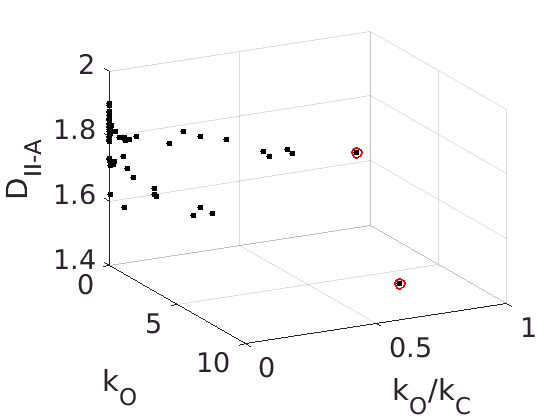

savefigloc = '/home/rachael/coarsegraining/Data/patchy/';
figure()
hold on
scatter3(grateO,grateO./grateC,fdim2a,20,'k','filled')
set(gca,'fontsize',20)

xlabel('k_O')
ylabel('k_O/k_C')
zlabel('D_{II-A}')
view([62.5,24.4])
grid on

[params3,front3] = paretoFront(params,[-grateO,-grateO./grateC fdim2a],[sgrateO,sgrateCO, sfdim2a]);
scatter3(-front3(:,1),-front3(:,2),front3(:,3),60,'r','linewidth',2)
savefig([savefigloc 'Pareto3d'])
saveas(gcf,[savefigloc 'Pareto3d'],'pdf')

This does not change if we go down to just 2 objectives, so let's do that.

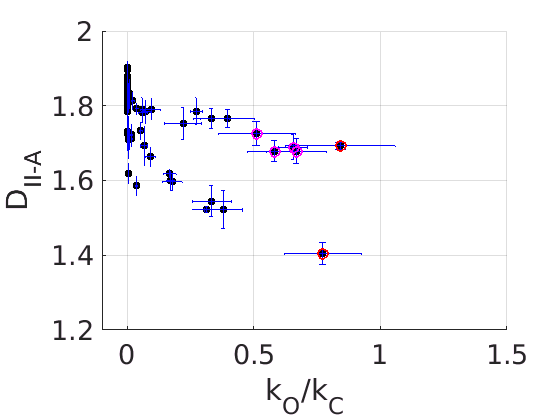

savefigloc = '/home/rachael/coarsegraining/Data/patchy/';

figure()
hold on
errorbarxy(grateO./grateC,fdim2a,sgrateCO,sfdim2a,{'k','b','b'})
set(gca,'fontsize',20)

xlabel('k_O/k_C')
ylabel('D_{II-A}')
%view([62.5,24.4])
grid on
xlim([-0.1 1.5])
[params2,front2] = paretoFront(params,[-grateO./grateC fdim2a],[sgrateO,sgrateCO, sfdim2a]);
scatter(-front2(:,1),front2(:,2),60,'r','linewidth',2)

%find also all points whose errorbars overlap with the Pareto Frontier points' errorbars
extrapoints = [];
extraparams = [];
for pi = 1%:size(front2,1)
    p = params2(pi,:);
    ind = find(params(:,1)==p(1) & params(:,2) == p(2) & params(:,3) == p(3));
    rint = [grateO(ind,:)./grateC(ind,:)-sgrateCO(ind,:) grateO(ind,:)./grateC(ind,:) + sgrateCO(ind,:)];
    fint = [fdim2a(ind,:) - sfdim2a(ind,:),fdim2a(ind,:) + sfdim2a(ind,:)];
    for i = 1:size(params,1)
       if i~=ind
           rinti = [grateO(i,:)./grateC(i,:)-sgrateCO(i,:) grateO(i,:)./grateC(i,:) + sgrateCO(i,:)];
           finti = [fdim2a(i,:)-sfdim2a(i,:), fdim2a(i,:) + sfdim2a(i,:)];
           if ~((rinti(2) < rint(1)) || (rinti(1) > rint(2))) && ~((finti(2) < fint(1)) || (finti(1) > fint(2)))
              extrapoints = [extrapoints; grateO(i,:)./grateC(i,:),fdim2a(i,:)]; 
              extraparams = [extraparams; params(i,:)];
           end
       end
    end
end
scatter(extrapoints(:,1),extrapoints(:,2),60,'m','linewidth',2)
savefig([savefigloc 'Pareto2d'])
saveas(gcf,[savefigloc 'Pareto2d'],'pdf')

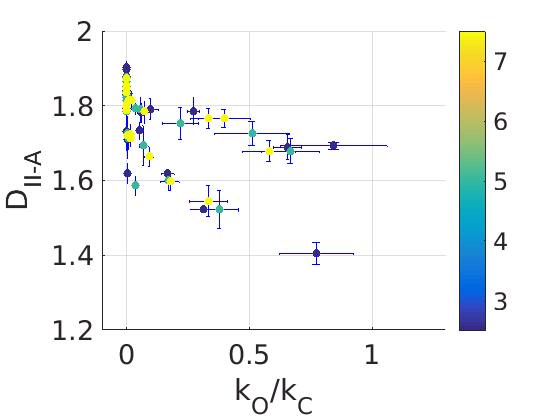


figure()
hold on
errorbarxy(grateO./grateC,fdim2a,sgrateCO,sfdim2a,{'k','b','b'})
scatter(grateO./grateC,fdim2a,40,params(:,1),'filled')
set(gca,'fontsize',20)
xlim([-0.1 1.5])
xlabel('k_O/k_C')
ylabel('D_{II-A}')
%view([62.5,24.4])
colorbar
grid on
savefig([savefigloc 'Pareto2deA'])
saveas(gcf,[savefigloc 'Pareto2deA'],'pdf')

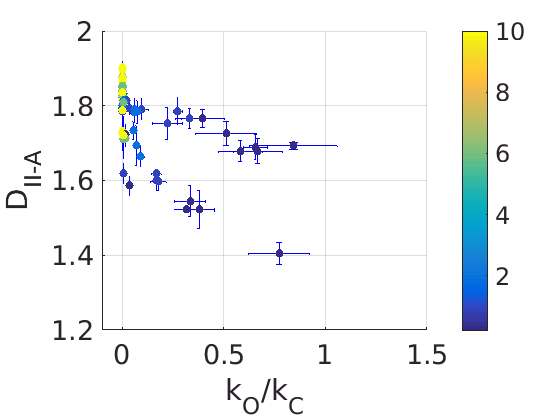


figure()
hold on
errorbarxy(grateO./grateC,fdim2a,sgrateCO,sfdim2a,{'k','b','b'})
scatter(grateO./grateC,fdim2a,40,params(:,2),'filled')
set(gca,'fontsize',20)
xlim([-0.1 1.5])
xlabel('k_O/k_C')
ylabel('D_{II-A}')
%view([62.5,24.4])
colorbar
grid on
savefig([savefigloc 'Pareto2deSC'])
saveas(gcf,[savefigloc 'Pareto2deSC'],'pdf')

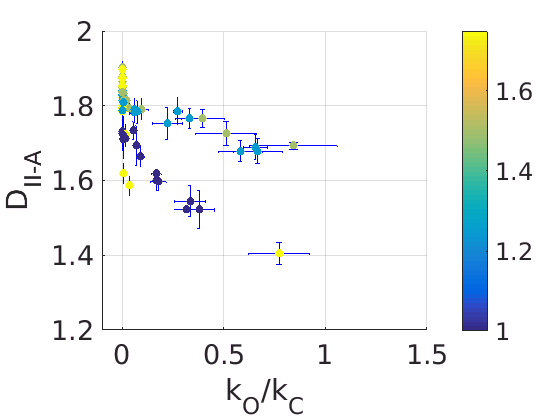


figure()
hold on
errorbarxy(grateO./grateC,fdim2a,sgrateCO,sfdim2a,{'k','b','b'})
scatter(grateO./grateC,fdim2a,40,params(:,3),'filled')
set(gca,'fontsize',20)
xlim([-0.1 1.5])
xlabel('k_O/k_C')
ylabel('D_{II-A}')
%view([62.5,24.4])
colorbar
grid on
savefig([savefigloc 'Pareto2dsSC'])
saveas(gcf,[savefigloc 'Pareto2dsSC'],'pdf')

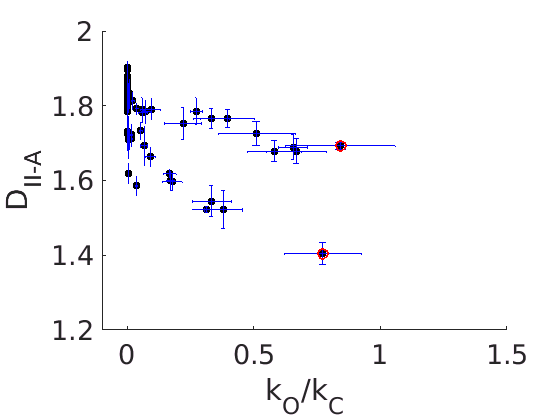

figure()
hold on
errorbarxy(grateO./grateC,fdim2a,sgrateCO,sfdim2a,{'k','b','b'})
set(gca,'fontsize',20)
xlabel('k_O/k_C')
ylabel('D_{II-A}')
xlim([-0.1 1.5])
scatter(-front3(:,2),front3(:,3),60,'r','linewidth',2)
savefig([savefigloc 'ParetoRatD2a'])
saveas(gcf,[savefigloc 'ParetoRatD2a'],'pdf')

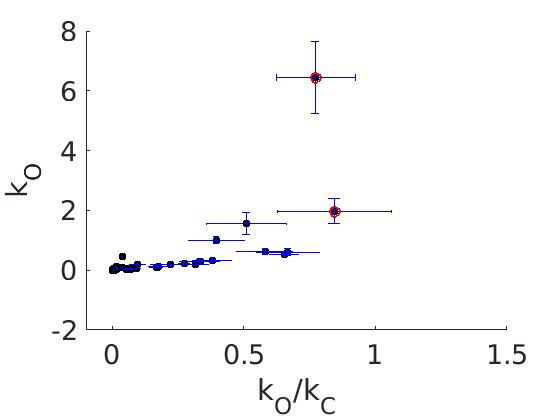


figure()
hold on
errorbarxy(grateO./grateC,grateO,sgrateCO,sgrateO,{'k','b','b'})
set(gca,'fontsize',20)
xlabel('k_O/k_C')
ylabel('k_O')
xlim([-0.1 1.5])

scatter(-front3(:,2),-front3(:,1),60,'r','linewidth',2)
savefig([savefigloc 'ParetoRatAbs'])
saveas(gcf,[savefigloc 'ParetoRatAbs'],'pdf')

We extract the Pareto front in three dimensions and display it in two for ease of viewing the data with error bars.  Next, we plot the parameter space occupied by the Pareto Frontier.

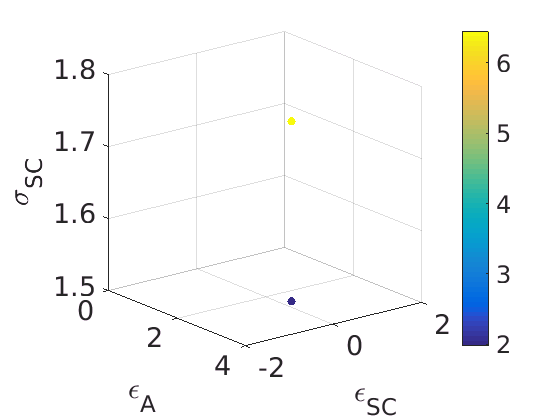

figure()
scatter3(params3(:,1),params3(:,2),params3(:,3),40,-front3(:,1),'filled')
hold on
set(gca,'fontsize',20)
xlabel('\epsilon_A')
ylabel('\epsilon_{SC}')
zlabel('\sigma_{SC}')
view([52.1,18])
grid on
colorbar

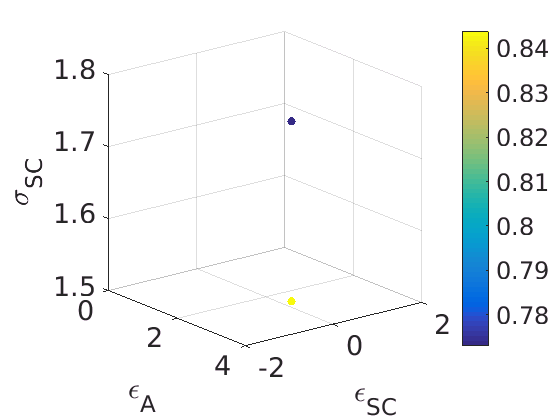


figure()
scatter3(params3(:,1),params3(:,2),params3(:,3),40,-front3(:,2),'filled')
hold on
set(gca,'fontsize',20)
xlabel('\epsilon_A')
ylabel('\epsilon_{SC}')
zlabel('\sigma_{SC}')
view([52.1,18])
grid on
colorbar

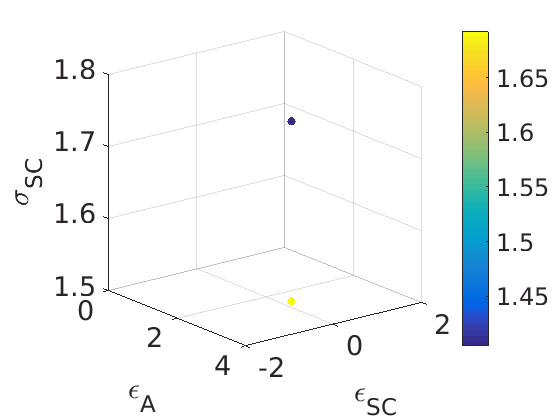


figure()
scatter3(params3(:,1),params3(:,2),params3(:,3),40,front3(:,3),'filled')
hold on
set(gca,'fontsize',20)
xlabel('\epsilon_A')
ylabel('\epsilon_{SC}')
zlabel('\sigma_{SC}')
view([52.1,18])
grid on
colorbar

There is a fairly clear trade-off here between overall optical cluster growth (increases with increasing side chain radius) and linearity of the aggregates (decreases with increasing side chain radius), but it is less obvious what controls the ratio of optical to contact growth.  It is strongly controlled by having a small SC well depth, as previously noted.

It would be nice to have a predictive model mapping the three parameters to each of the different objectives (or the overall vector objective function.)  

Let's play around with some regression tree analysis for a little bit.

## Using a Regression Tree as a predictive model 

First, let's compare cross-validation by hand with cross-validation done in the tree.

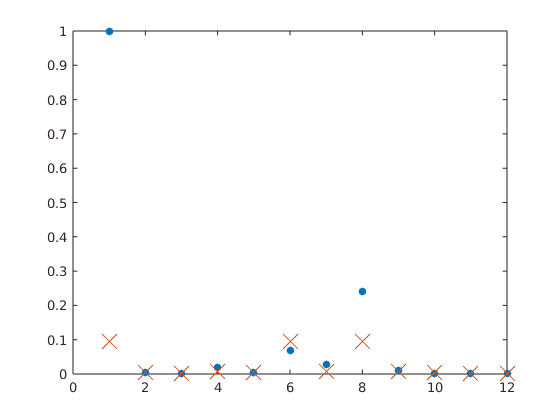

%keep 3/4 of the data randomly, put 12 random data points separate for testing
rperm = randperm(48);
datain = params;
dataout = [grateO/max(grateO) grateO./grateC fdim2b];
datain = datain(rperm,:);
dataout = dataout(rperm,:);
trainin = datain(1:36,:);
trainout = dataout(1:36,:);
testin = datain(37:end,:);
testout = dataout(37:end,:);

tree1 = fitrtree(trainin,trainout(:,1),'PredictorNames',{'epsA','epsSC','sigSC'});
figure()
plot(testout(:,1),'.','markersize',20)
hold on
plot(predict(tree1,testin),'x','markersize',15)

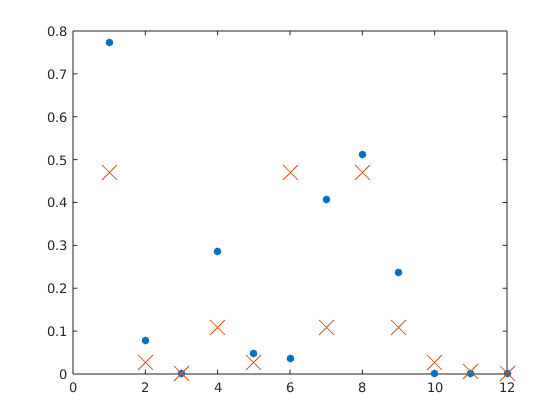




tree2 = fitrtree(trainin,trainout(:,2));

figure()
plot(testout(:,2),'.','markersize',20)
hold on
plot(predict(tree2,testin),'x','markersize',15)

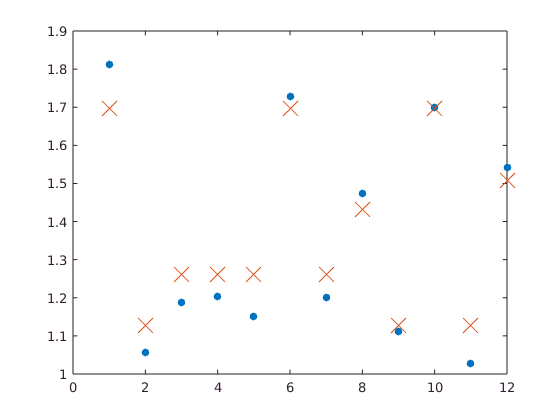


tree3 = fitrtree(trainin,trainout(:,3));

figure()
plot(testout(:,3),'.','markersize',20)
hold on
plot(predict(tree3,testin),'x','markersize',15)


%now try with a BaggedTree ensemble
tic
trees1 = TreeBagger(100,trainin,trainout(:,1),'Method','regression','PredictorNames',{'eps_A','eps_SC','sigma_SC'});
toc

Elapsed time is 0.193035 seconds.


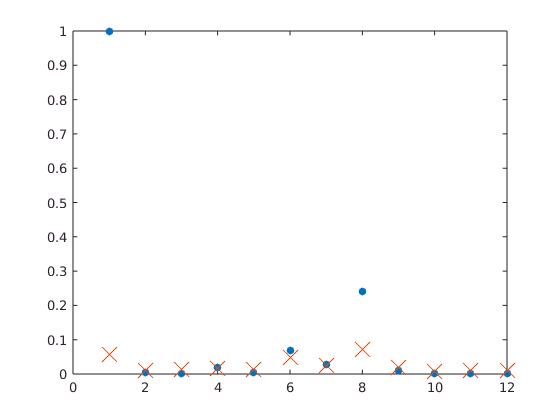

figure()
plot(testout(:,1),'.','markersize',20)
hold on
plot(predict(trees1,testin),'x','markersize',15)


tic
trees2 = TreeBagger(100,trainin,trainout(:,2),'Method','regression','PredictorNames',{'eps_A','eps_SC','sigma_SC'});
toc

Elapsed time is 0.193869 seconds.


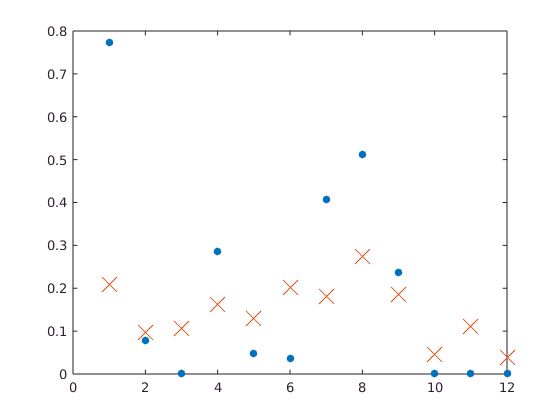

figure()
plot(testout(:,2),'.','markersize',20)
hold on
plot(predict(trees2,testin),'x','markersize',15)


tic
trees3 = TreeBagger(100,trainin,trainout(:,3),'Method','regression','PredictorNames',{'eps_A','eps_SC','sigma_SC'});
toc

Elapsed time is 0.191414 seconds.


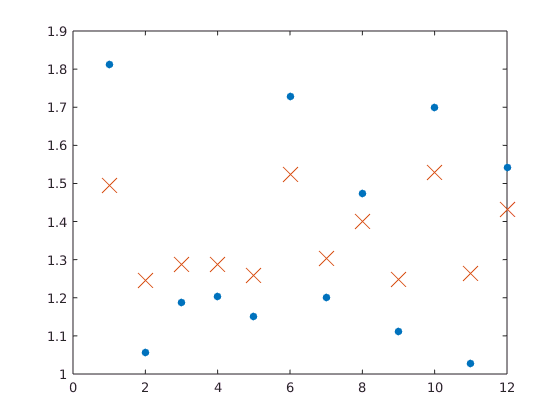

figure()
plot(testout(:,3),'.','markersize',20)
hold on
plot(predict(trees3,testin),'x','markersize',15)

Okay, well, neither is great, but a single tree is more interpretable, so let's go ahead and do that.  Let's take a look at the trees produced by ten-fold cross-validation on the full parameter set.

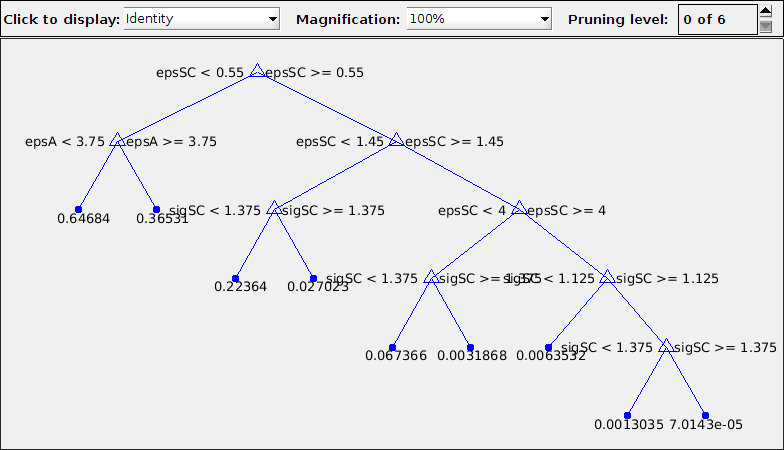

datain = params;
dataout = [grateO./grateC fdim2a];
tree1 = fitrtree(datain,dataout(:,1),'PredictorNames',{'epsA','epsSC','sigSC'});
cv1 = crossval(tree1);
view(tree1,'mode','graph')

tree2 = fitrtree(datain,dataout(:,2),'PredictorNames',{'epsA','epsSC','sigSC'});

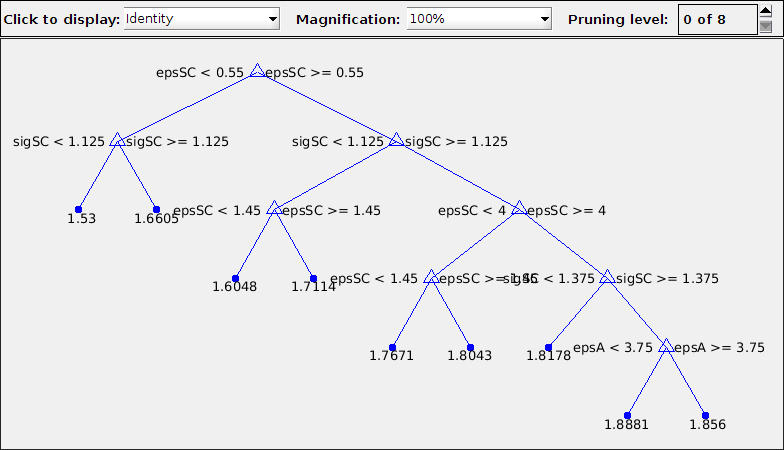

cv2 = crossval(tree2);
view(tree2,'mode','graph')

Of note, as expected, we split on SC well depth for the rate ratio initially and then on epsA for the large rates as noted earlier.  We then split further on epsSC for the smaller rates.

For d2b, which is moderately anticorrelated with the optical cluster growth rate (and the ratio of the rates), we split first on epsSC but then split on side chain radius (as expected from an analysis of d2b).

Now let's go ahead and use these to compute a Pareto Frontier for things with epsSC < 1 kT

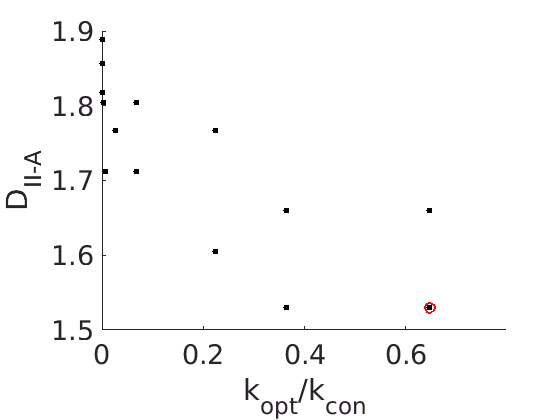

epsSC = 0.1:0.1:10.0;
sigSC = 1:0.1:1.75;
epsA = [2.5 5 7.5];
predictParams = zeros(length(epsSC)*length(sigSC)*length(epsA),3);
ind = 1;
for a = epsA
    for sc = epsSC
        for sig = sigSC
            predictParams(ind,:) = [a sc sig];
            ind = ind+1;
        end
    end
end
kratpred = predict(tree1,predictParams);
fdimapred = predict(tree2,predictParams);
figure()
scatter(kratpred,fdimapred,20,'k','filled')
set(gca,'fontsize',20)

xlabel('k_{opt}/k_{con}')
ylabel('D_{II-A}')
hold on
[params2,front2] = paretoFront(predictParams,[-kratpred fdimapred],[]);
scatter(-front2(:,1),front2(:,2),60,'r','linewidth',2)
savefig([savefigloc 'ParetoPredict'])
saveas(gcf,[savefigloc 'ParetoPredict'],'pdf')

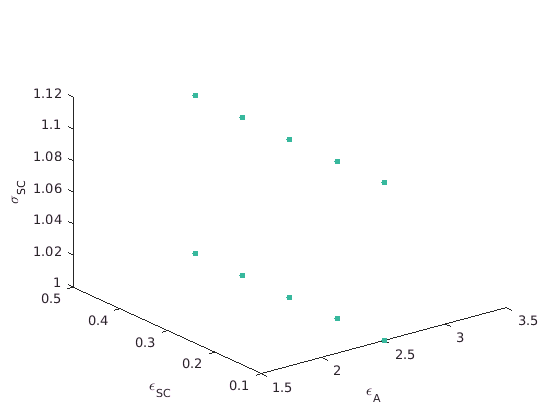



figure()
hold on
scatter3(params2(:,1),params2(:,2),params2(:,3),20,-front2(:,1),'fill');
xlabel('\epsilon_A')
ylabel('\epsilon_{SC}')
zlabel('\sigma_{SC}')
view(3)


figure()
hold on
scatter3(params2(:,1),params2(:,2),params2(:,3),20,front2(:,2),'fill');
xlabel('\epsilon_A')
ylabel('\epsilon_{SC}')
zlabel('\sigma_{SC}')
view(3)